# Example 1.1 - Flapped Airfoil with vertical displacements

Flapped airfoil with steady aerodynamic model to demonstrate the three representations of LTI systems. 

This is a modification of the example in Palacios & Cesnik to include three different feedback gains between the plunge rate and the flap input.

Written by Rafa Palacios ([r.palacios@imperial.ac.uk](mailto:r.palacios@imperial.ac.uk))

Latest update: April 2024

close all, clear all

% Define coefficients
mu_a_overV=2;  % (\mu_a)/(V)
mu_b=1;
omega_h=4;

% Compute state-space matrices;
A=[[0 1]; [-omega_h^2 -mu_a_overV]];
B=[0; -mu_b];
C=[0 1];     % Output is vertical velocity (plunge rate).
D=[];

% Build state-space system
sys1=ss(A,B,C,D);

% Loop through different gains
for K=[0.1 1 10]

    % Add feedback
    sys2=K;
    
    sys=feedback(sys1,sys2,+1);

    tf(sys)  % Output transfer function
    figure(1)
    bode(sys), hold on % Compute the frequency-response function 

    figure(2)
    impulse(sys, 4*2*pi/omega_h), hold on  % Compute impulse response for roughly 4 cycles
end

ans =
 
         -s
  ----------------
  s^2 + 2.1 s + 16
 
Continuous-time transfer function.
Model Properties
ans =
 
        -s
  --------------
  s^2 + 3 s + 16
 
Continuous-time transfer function.


Plot the frequency response function for the three feedback gains in log scale. Input is the commanded flap deflection and output is the plunge rate $\dot{h}$.

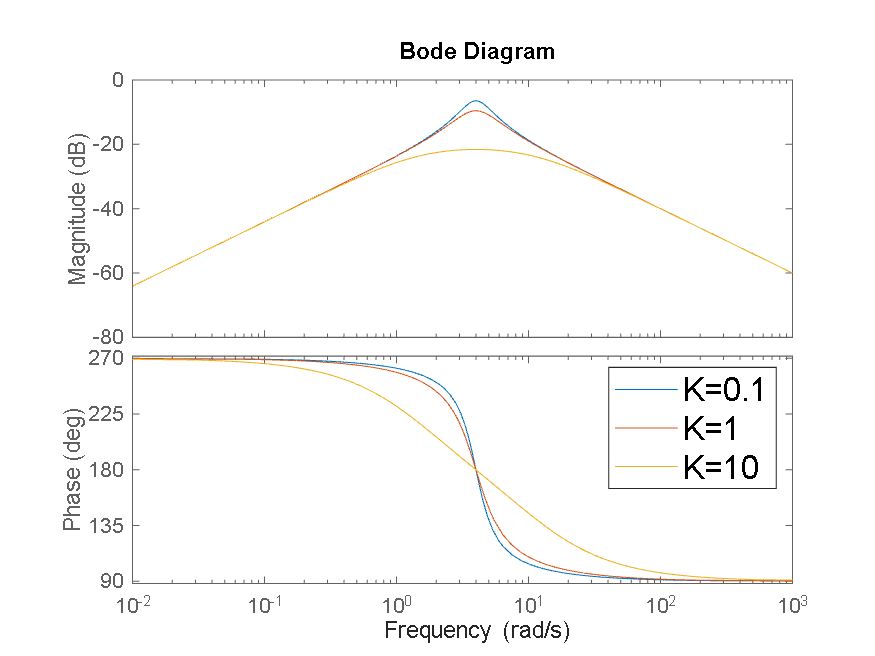

figure (1), legend('K=0.1','K=1','K=10','FontSize',16)

Plot the impulse response for the three feedback gains in log scale. Input is the commanded flap deflection and output is the plunge rate $\dot{h}$.

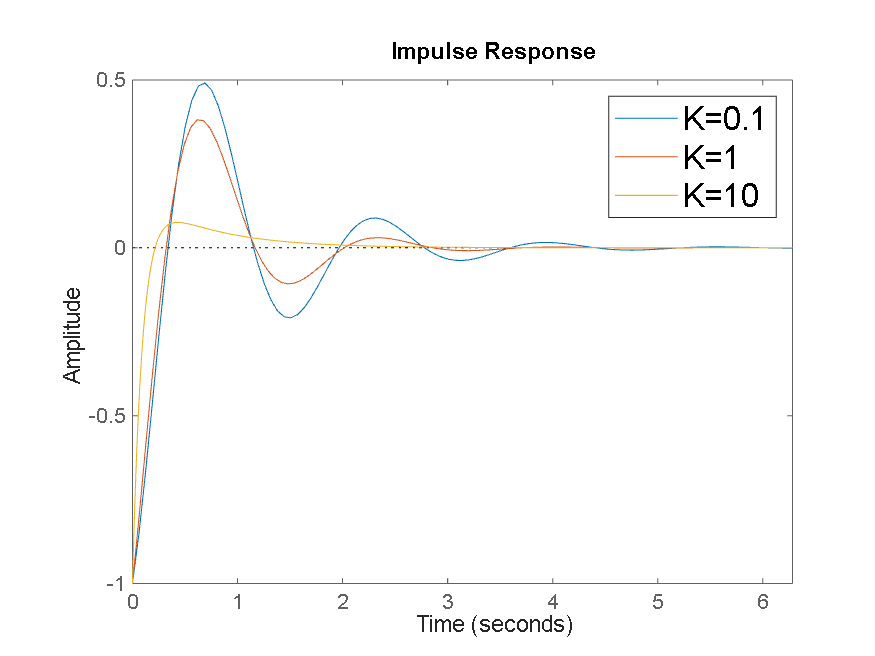

figure (2), legend('K=0.1','K=1','K=10','FontSize',16)

Plot eigenvalues of the system for varying velocity 

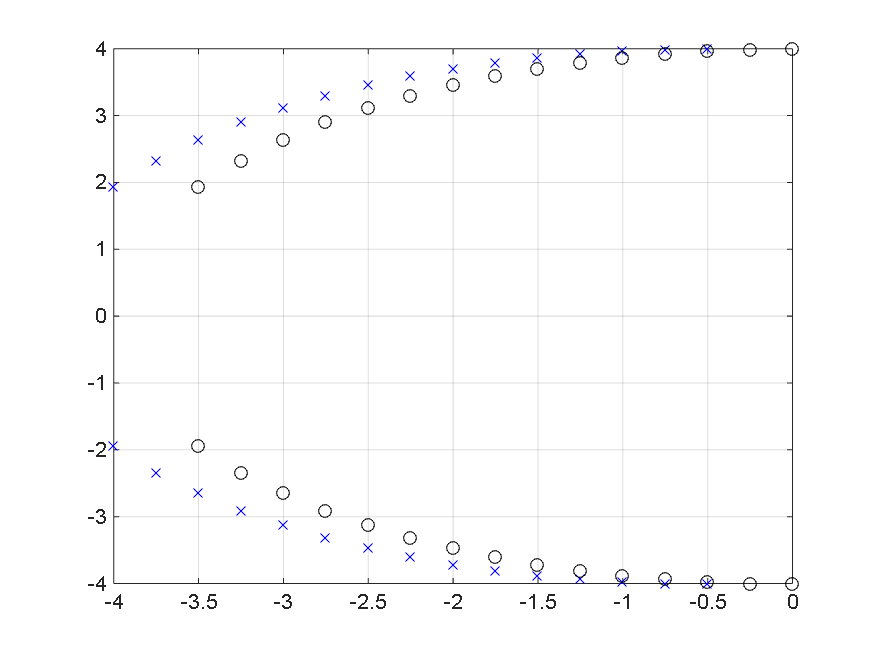

figure(3)
for mu_a_overV=0:0.5:7;
    % Rewrite the system matrix.
    A=[[0 1]; [-omega_h^2 -mu_a_overV]];
    % Corresponding open-loop and closed-loop transfer functions.
    sys1=ss(A,B,C,D);
    sys2=1;
    sys=feedback(sys1,sys2,+1);
    plot(real(eig(sys1)),imag(eig(sys1)),'ko'), hold on  % Circles for open-loop
    plot(real(eig(sys)),imag(eig(sys1)),'bx')            % crosses for closed-loop
end, grid on